# 6DOF SIMULATION OF LUNAR LANDER

clear all; close all;
global m Ixx Iyy Izz roll0

Ixx = 1;
Iyy = 1;
Izz = 1;

K_phi = 2;
K_P = 3;
K_theta = 4;
K_Q = 6;
K_psi = 0.3;
K_R = 0.4;

## INITIALIZE STATE

pos = [0 0 0];
vel = [1 0 0];
ang = [0 0.3 0];
ang_vel = [0 0 0];
roll0 = 0;

m = 10;  % mass of lunar-lander, kg

initial_state = [pos vel ang ang_vel];
state = initial_state;

## Guidance

% T = 600;
% n = 600;
% dt = T/n;
% ts = linspace(0,T,n+1);
% A = eye(6);
% B = zeros(6,3);
% x_des = zeros(1,6);
% x_0 = [10000,10000,15000,-1500/sqrt(2),-1500/sqrt(2),0];
% for i = 1 : 3
%   A(i,i+3) = dt;
%   B(i,i) = dt^2/2;
%   B(i+3,i) = dt;
% end
% 
% x = zeros(6,n+1);
% x(:,1) = x_0;
% G = zeros(6,3*n);
% P = zeros(6,6*n);
% g = 1.63;
% b = [0, 0, -0.5*g*dt^2, 0, 0, -g*dt];
% bs = repmat(b,1,600);
% for i = 1 : n
%   G(:,3*i-2:3*i) = A^(n-(i+1))*B;
%   P(:,6*i-5:6*i)= A^(n-(i+1));
%   Q = P*bs';
% end
% 
% first = A^n*x_0';
% u_temp = lsqr(G, x_des' - first - Q );
% acc = reshape(u_temp,[3,600])';
acc = [0.01 1 0];

## acc to euler angle

% yaw = atan2(acc(2),acc(1));
% pitch = atan2(-1*acc(3),norm(acc(1:2)));
% roll = roll0;

## Controller

Moment = [0 0 0];

## SIMULATION

dt = 0.1;

z = pos(3);
i = 1;
tic
while(z < 100)
    save_state(i,:) = state;
    
    % 6DOF - RK4
    Num = 1;
    save_s = 0;
    sum_k = 0;
    time = 0;
    angle_cmd = acc2angle(acc);

    phi = save_state(i,7);
    theta = save_state(i,8);
    psi = save_state(i,9);

    P = save_state(i,10);
    Q = save_state(i,11);
    R = save_state(i,12);
    
    phi_cmd = angle_cmd(1);
    theta_cmd = angle_cmd(2);
    psi_cmd = angle_cmd(3);

    Moment_cmd(1) = -K_P*P + K_phi*(phi_cmd - phi);
    Moment_cmd(2) = -K_Q*Q + K_theta*(theta_cmd - theta);
    Moment_cmd(3) = -K_R*R + K_psi*(psi_cmd - psi);

    [T,Moment] = Cal_thrust(m*norm(acc), Moment_cmd);

    while(Num < 5)
        [X,dX] = UPDATE_DERIV(acc, Moment, state);
        [X,time,save_s,sum_k,Num] = RK4(X,dX,save_s,sum_k,time,Num,dt);
    end
    state = X;
    z = state(3);
    
    i = i + 1;
end
toc

경과 시간은 0.107556초입니다.


## Plot

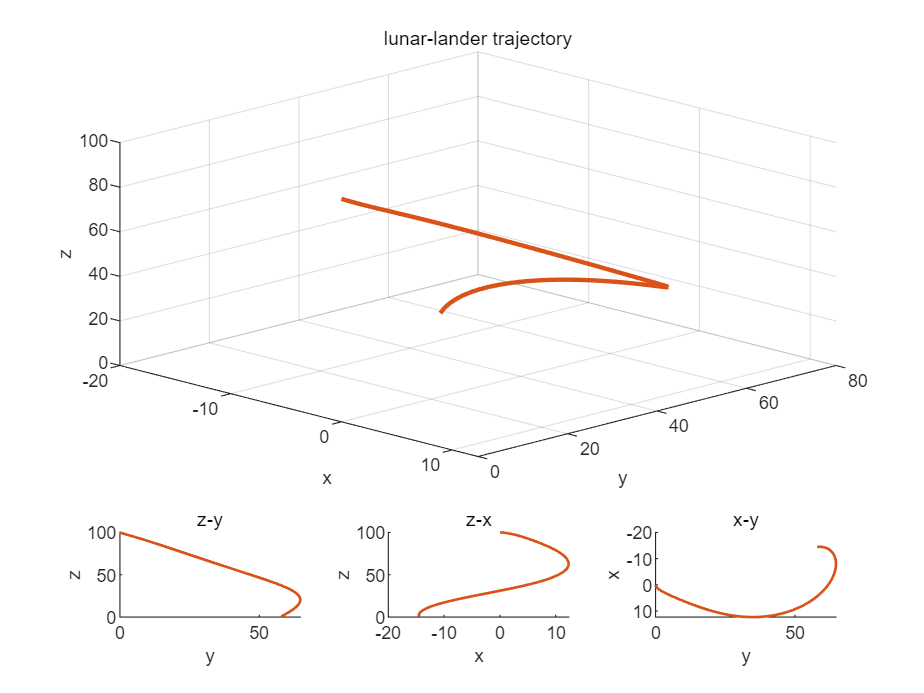

% Trajectory plot
figure('Color','White')
tiledlayout(4,3)
nexttile([3 3])
plot3(save_state(:,1),save_state(:,2),100-save_state(:,3),'Color','#D95319','LineWidth',2);
title('lunar-lander trajectory')
xlabel('x'); ylabel('y'); zlabel('z');
view(45, 30)
grid on

nexttile;
plot3(save_state(:,1),save_state(:,2),100-save_state(:,3),'Color','#D95319','LineWidth',1.2);
title('z-y')
xlabel('x'); ylabel('y'); zlabel('z');
view(90, 0)

nexttile;
plot3(save_state(:,1),save_state(:,2),100-save_state(:,3),'Color','#D95319','LineWidth',1.2);
title('z-x')
xlabel('x'); ylabel('y'); zlabel('z');
view(0,0)

nexttile;
plot3(save_state(:,1),save_state(:,2),100-save_state(:,3),'Color','#D95319','LineWidth',1.2);
title('x-y')
xlabel('x'); ylabel('y'); zlabel('z');
view(90,90)
% 
% % Trajectory animation plot
% x_max = max(save_state(:,1));
% y_max = max(save_state(:,2));
% z_max = max(100 - save_state(:,3));
% figure(2)
% pause(1)
% hold on
% for i = 1 : length(save_state(:,1))
%     ax = gcf;
%     plot3(save_state(i,1),save_state(i,2),100-save_state(i,3),'.b');
%     title('lunar-lander trajectory - Animate')
%     xlabel('x'); ylabel('y'); zlabel('z');
%     grid on
%     pause(0.1)
%     axis([0 x_max 0 y_max 0 z_max])
%     view(45, 30)
% end
hold off

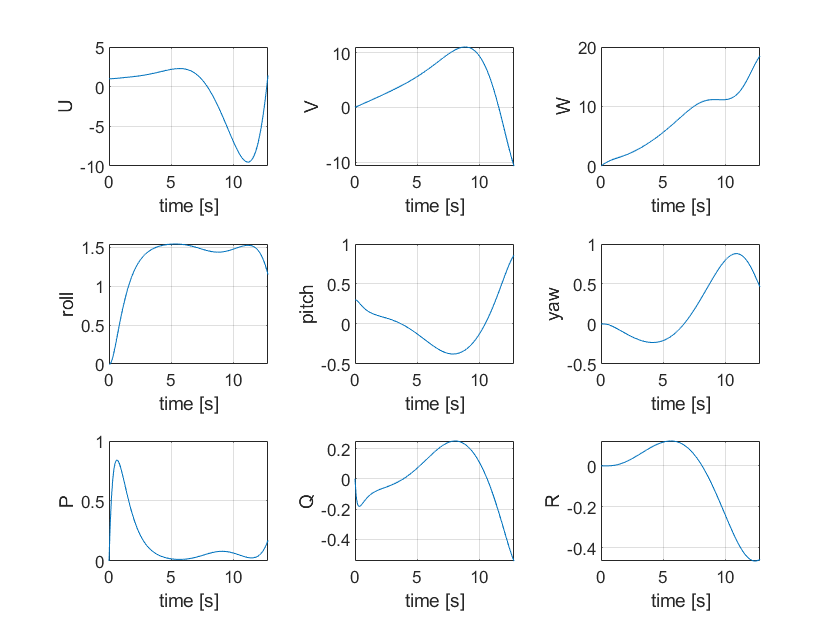

% states
figure('Color','White')
tiledlayout(3,3)
tf = length(save_state(:,1)) * dt;
for i = 4 : 12
    nexttile;
    plot(0:dt:tf-dt, save_state(:,i));
    xlabel('time [s]')
    id = state_id(i);
%     title(id)
    ylabel(id)
    grid on
end